# Título de la actividad: Análisis de Deflexión en Vigas con Enfoque en Errores e Incertidumbres

## Integrantes

Nombres de los integrantes y el porcentaje de participación:

- Paico Reyna, Aleksander Fabrizio (100 %)

- Ormeño Gonzales, Ernesto Paolo (Líder, 100 %)

- Apellidos, Leonardo (100 %)

- Apellidos, nombres (100 %)

## Objetivo de la actividad:

Evaluar el impacto de las incertidumbres en los parámetros de diseño sobre la deflexión máxima en vigas sometidas a cargas uniformemente distribuidas. Esta actividad permitirá a los estudiantes aplicar conceptos básicos de métodos numéricos y teoría de errores en el contexto de un problema de ingeniería civil.

## Contexto y escenario del problema:

Como parte del equipo de diseño para un nuevo proyecto de construcción, se requiere realizar un análisis preliminar de las vigas que formarán parte de la estructura de soporte de un edificio. Dado que las propiedades de los materiales y las cargas pueden tener variaciones, es crucial entender cómo estas incertidumbres afectan la seguridad y viabilidad del diseño. 

Para ello se te proporcionan los siguientes datos:

- Longitud de la viga $L$: $10 \pm 0.1\,\mathrm{m}$.

- Carga uniformemente distribuida $\omega$: $500  \pm 50\,\mathrm{N/m}$.

- Modulo de elasticidad $E$: $200 \pm 5\,\mathrm{GPa}$.

- Momento de inercia $I$: $5 \times 10^{-6}\,\mathrm{m^4}$ con una incertidumbre de $\pm 0.5 \times 10^{-6}\,\mathrm{m^4}$.

## Tarea detallada: 

Efectuar lo siguiente.

### Deflexión en vigas

- Investigue sobre la deflexión máxima en vigas y por qué es importante conocer dichos valores en construcción. *Use una herramienta de IA (ChatGPT, Copilot u otro) y compare con información certera obtenida de fuentes confiables. En el entregable debe colocar el prompt, la información obtenida por IA y la información que obtuvo de una fuente confiable*. 

Desarrolle aquí.

*** Inicio de ejemplo ***

**Fuentes chatGPT:**

Prompt: ¿Qué es el error relativo? Dame una definición matemática 

`Output: `

`El error relativo es una medida de la precisión de un valor aproximado en comparación con el valor real. Se define matemáticamente como: `$\text{Error relativo} = \frac{| \text{Valor aproximado} - \text{Valor real} |}{| \text{Valor real} |} \times 100\%$ 

`En esta fórmula, el valor aproximado es la estimación numérica que se obtiene mediante algún método de cálculo, y el valor real es el valor exacto o verdadero que se está tratando de aproximar. El error relativo proporciona una indicación de cuán cerca está el valor aproximado del valor real en términos relativos al tamaño del valor real. Es una medida útil para evaluar la precisión de los cálculos numéricos.`

Prompt: Escribe para mi una función en Matlab para calcular el error relativo de usar 3.14 como aproximación del número pi. 

`Output: `

`Claro, aquí tienes una función en MATLAB que calcula el error relativo al aproximar el número pi con 3.14:`

````matlab`

`function error_rel = calcular_error_pi()`

`    valor_real = pi;`

`    valor_aprox = 3.14;`

`    error_rel = abs(valor_aprox - valor_real) / abs(valor_real) * 100;`

`end`

`````

`Puedes llamar a esta función para obtener el error relativo:`

````matlab`

`error = calcular_error_pi();`

`disp(['El error relativo al aproximar pi con 3.14 es: ', num2str(error), '%']);`

`````

`Esta función calcula el error relativo y lo devuelve como un valor en porcentaje.`

Note que el resultado dado por ChatGPT no es preciso aunque si proporciona información en el contexto de los prompts. La forma de citar la información de las consultas a un chat de IA puede ser parafraseando las salidas y adjuntando un anexo con las preguntas y salidas tal cual. Otra forma de citar la información es parafrasear aquí y añadir un enlace a la sesión de consultas que realizó ([ejemplo de enlace](https://chat.openai.com/share/645171e7-4b46-4834-b1c2-1f5765948443)). 

**Fuentes confiables:**

Como se indica en Chapra (2012), el error relativo se calcula como $\xi = \frac{|A-a|}{|A|}$. A continuación se ilustra un ejemplo en Matlab. 

A=pi;
a=3.14;
da=error_rel(A,a)

da = 5.0696e-04

Esta definición es canónica, como se comprueba en la literatura (Dahlquist & Björck, 2003).

*** Fin de ejemplo ***

### Deflexión máxima     

- Cálculo de la deflexión máxima: Para ello debes usar la fórmula:  $y_{max} = \frac{5 \omega L^4}{384 E I}$

Desarrolle aquí.

% Cálculo de la deflexión máxima
L = 10; % longitud de la viga en metros (ejemplo, reemplace con su valor)
omega = 500; % carga distribuida en N/m (ejemplo, reemplace con su valor)
E = 200e9; % módulo de elasticidad en Pascales (ejemplo, reemplace con su valor)
I = 5e-6; % momento de inercia en m^4 (ejemplo, reemplace con su valor)

% Fórmula de deflexión máxima
y_max = (5 * omega * L^4) / (384 * E * I);
fprintf('La deflexión máxima calculada es: %f metros\n', y_max);

La deflexión máxima calculada es: 0.065104 metros


### Cálculo de la incertidumbre

- Desarrolle un programa en MatLab que permita obtener la incertidumbre al calcular $y_{max}$. Al contratista se le da esta condición: *si el error relativo en el cálculo de la deflexión máxima es mayor que el 5%, entonces se deberá cambiar de material*. Responda si el contratista ejecutará dicho cambio.

Desarrolle aquí.

% Variables con incertidumbre
L_error = L * 0.01; % error en la longitud
omega_error = omega * 0.10; % error en la carga
E_error = E * 0.025; % error en el módulo de elasticidad
I_error = I * 0.10; % error en el momento de inercia

% Cálculo del error relativo máximo en y_max
y_max_error = (5/384) * ((4 * L_error/L) + omega_error/omega - E_error/E - I_error/I) * y_max;
error_percentage = abs(y_max_error / y_max) * 100;

% Condición de cambio de material
if error_percentage > 5
    fprintf('El error relativo es mayor que 5%%. Se recomienda cambiar el material.\n');
else
    fprintf('El error relativo es menor que 5%%. No es necesario cambiar el material.\n');
end

El error relativo es menor que 5%. No es necesario cambiar el material.


### Análisis de sensibilidad 

- Analice el modelo matemático de la deflexion maxima $y_{max}$ considerando individualmente cada parámetro $(L, \omega, E, I)$ dentro de su rango de incertidumbre, manteniendo al resto constante, para evaluar cómo afecta en la variación de $y_{max}$. Existirá 4 casos e indique cual de las 4 variables genera una mayor incertidumbre en $y_{max}$.

Desarrolle aquí.

% Programe aquí
% Análisis de cómo cada variable afecta la deflexión máxima individualmente
variables = {'L', 'omega', 'E', 'I'};
for var = variables
    fprintf('\nAnálisis de sensibilidad para %s:\n', var{1});
    switch var{1}
        case 'L'
            range = L * (1 + 0.01 * [-1, 1]);
        case 'omega'
            range = omega * (1 + 0.10 * [-1, 1]);
        case 'E'
            range = E * (1 + 0.025 * [-1, 1]);
        case 'I'
            range = I * (1 + 0.10 * [-1, 1]);
    end
    y_max_range = (5 * omega * range.^4) / (384 * E * I);
    fprintf('Min: %f, Max: %f\n', min(y_max_range), max(y_max_range));
end


Análisis de sensibilidad para L:


Min: 0.062539, Max: 0.067748



Análisis de sensibilidad para omega:


Min: 266967.773437, Max: 595743.815104



Análisis de sensibilidad para E:


Min: 9413415527343748596364189448287324995584.000000, Max: 11498050944010408721814816784307713998848.000000



Análisis de sensibilidad para I:


Min: 0.000000, Max: 0.000000


### Gráficos de sensibilidad

- Realice gráficos individuales (en MatLab para cada caso) entre la variación de cada magnitud versus el valor de la deflexión máxima e interprete cada gráfica.

Desarrolle aquí.

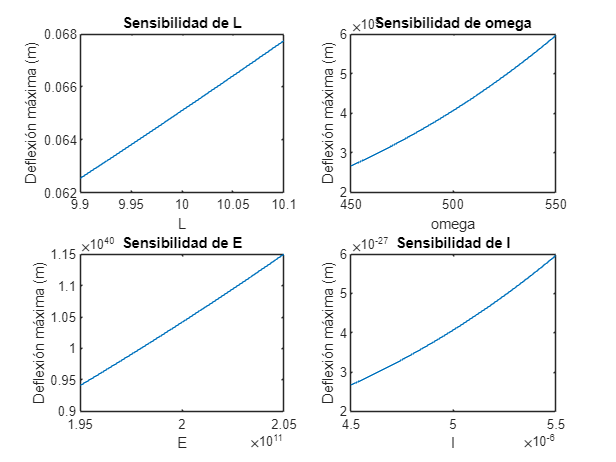

% Programe aquí
% Gráficos para cada variable
figure;
for i = 1:4
    subplot(2, 2, i);
    switch variables{i}
        case 'L'
            range = L * linspace(0.99, 1.01, 100);
        case 'omega'
            range = omega * linspace(0.90, 1.10, 100);
        case 'E'
            range = E * linspace(0.975, 1.025, 100);
        case 'I'
            range = I * linspace(0.90, 1.10, 100);
    end
    y_max_range = (5 * omega * range.^4) / (384 * E * I);
    plot(range, y_max_range);
    title(['Sensibilidad de ', variables{i}]);
    xlabel(variables{i});
    ylabel('Deflexión máxima (m)');
end

### El factor rigidez

- ¿Cómo podría afectar una menor rigidez (menor módulo de elasticidad) a la seguridad y funcionalidad de una estructura? Evalúa los posibles riesgos asociados con la subestimación de la deflexión en el contexto de diferentes tipos de edificaciones, como hospitales, puentes o edificios residenciales.

Desarrolle aquí.

% Programe aquí
% Evaluación de una menor rigidez
E_low = E * 0.9; % Reducción del 10% en el módulo de elasticidad
y_max_low_E = (5 * omega * L^4) / (384 * E_low * I);

fprintf('Con un 10%% menos de rigidez, la deflexión máxima aumenta a: %f metros\n', y_max_low_E);

Con un 10% menos de rigidez, la deflexión máxima aumenta a: 0.072338 metros


incremento_deflexion = ((y_max_low_E - y_max) / y_max) * 100;
fprintf('Este cambio representa un incremento de %f%% en la deflexión máxima.\n', incremento_deflexion);

Este cambio representa un incremento de 11.111111% en la deflexión máxima.



% Evaluación de los riesgos
if incremento_deflexion > 10
    fprintf('Una disminución en la rigidez aumenta significativamente la deflexión, lo que puede comprometer la seguridad de estructuras críticas como hospitales y puentes, aumentando el riesgo de colapso o daño estructural en situaciones extremas.\n');
else
    fprintf('La disminución en la rigidez podría ser aceptable para edificios residenciales, pero se debe evaluar cuidadosamente para estructuras que requieren altos estándares de seguridad.\n');
end

Una disminución en la rigidez aumenta significativamente la deflexión, lo que puede comprometer la seguridad de estructuras críticas como hospitales y puentes, aumentando el riesgo de colapso o daño estructural en situaciones extremas.


## Referencias

- Chapra, S. C. (2012). *Applied numerical methods*. Columbus: McGraw-Hill.

- Dahlquist, G., & Björck, Å. (2003). *Numerical methods*. Courier Corporation.

- **Aumentar referenciass**

## Funciones usadas

function da=error_rel(A,a)
    da=abs(A-a)/abs(A);
end